# Flux Balance Analysis - part 2

## Author(s): Ronan Fleming, Ines Thiele, University of Galway; Jeff Orth, University of California, San Diego.

## Reviewer(s): 

## INTRODUCTION

In this tutorial, Flux Balance Analysis (FBA) is introduced using the E. coli core model, with functions in the COBRA Toolbox v3.0 [2].  

## E. coli core model

A map of the E. coli core model is shown in Figure 1. 

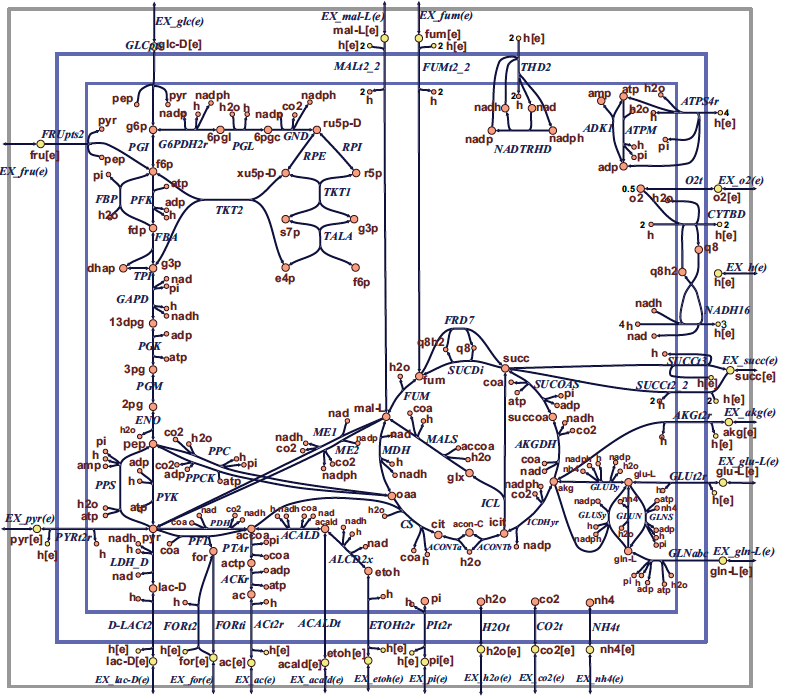

**Figure 1**  **Map of the core E. coli metabolic network. ** Orange circles represent cytosolic metabolites, yellow circles represent extracellular metabolites, and the blue arrows represent reactions.  Reaction name abbreviations are uppercase (blue) and metabolite name abbreviations are lowercase (rust colour).  This flux map was drawn using SimPheny and edited for clarity with Adobe Illustrator. 

## MATERIALS - EQUIPMENT SETUP

Please ensure that all the required dependencies (e.g. , `git` and `curl`) of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html). Please ensure that the COBRA Toolbox has been initialised (tutorial_initialize.mlx) and verify that the pre-packaged LP and QP solvers are functional (tutorial_verify.mlx).

## PROCEDURE

## Load E. coli core model

The most direct way to load a model into The COBRA Toolbox is to use the `readCbModel` function. For example, to load a model from a MAT-file, you can simply use the filename (with or without file extension). 

fileName = 'ecoli_core_model.mat';
if ~exist('modelOri','var')
    modelOri = readCbModel(fileName);
end
%backward compatibility with primer requires relaxation of upper bound on
%ATPM
modelOri = changeRxnBounds(modelOri,'ATPM',1000,'u');
model = modelOri;

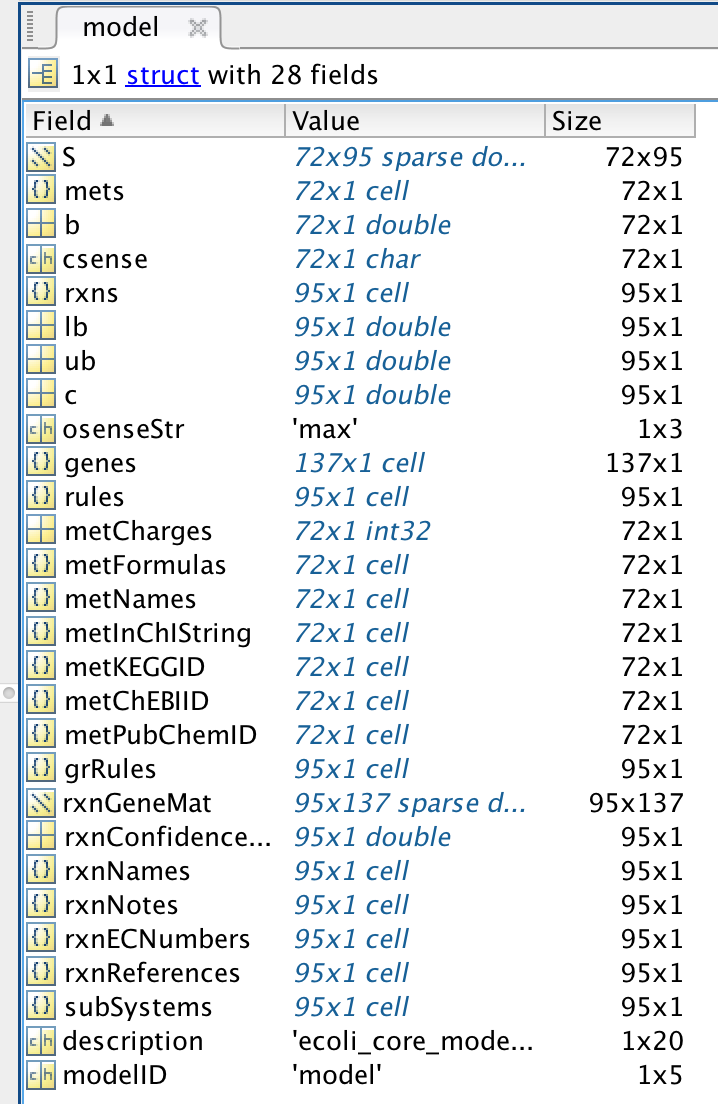

The meaning of each field in a standard model is defined in the [standard COBRA model field definition](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/notes/COBRAModelFields.md).

In general, the following fields should always be present: 

- **S**, the stoichiometric matrix

- **mets**, the identifiers of the metabolites

- **b**, Accumulation (positive) or depletion (negative) of the corresponding metabolites. 0 Indicates no concentration change.

- **csense**, indicator whether the b vector is a lower bound ('G'), upper bound ('L'), or hard constraint 'E' for the metabolites.

- **rxns**, the identifiers of the reactions

- **lb**, the lower bounds of the reactions

- **ub**, the upper bounds of the reactions

- **c**, the linear objective

- **genes**, the list of genes in your model 

- **rules**, the Gene-protein-reaction rules in a computer readable format present in your model.

- **osenseStr**, the objective sense either `'max'` for maximisation or `'min'` for minimisation

## Checking the non-trivial constraints on a model

#### What are the default constraints on the model? 

#### Hint: `printConstraints`

printConstraints(model,-1000,1000)

MinConstraints:
ATPM	8.39
EX_glc(e)	-10
maxConstraints:


## Example 5.  Robustness analysis

Another method that uses FBA to analyze network properties is robustness analysis [14].  In this method, the flux through one reaction is varied and the optimal objective value is calculated as a function of this flux.  This reveals how sensitive the objective is to a particular reaction.  There are many insightful combinations of reaction and objective that can be investigated with robustness analysis.  One example is examination of the effects of nutrient uptake on growth rate.  

#### What is the effect of varying glucose uptake rate on growth? At what uptake rates does glucose alone constrain growth?

#### Hint: fix the oxygen uptake rate to 17 mmol gDW-1 hr-1

To determine the effect of varying glucose uptake on growth, first use changeRxnBounds to set the oxygen uptake rate (EX_o2(e)) to 17 mmol gDW-1 hr-1, a realistic uptake rate.  Then, use a for loop to set both the upper and lower bounds of the glucose exchange reaction to values between 0 and -20 mmol gDW-1 hr-1, and use optimizeCbModel to perform FBA with each uptake rate.  Be sure to store each growth rate in a vector or other type of Matlab list.  The COBRA Toolbox also contains a function for performing robustness analysis (robustnessAnalysis) that can perform these functions. The full code to perform this robustness analysis is:

model = modelOri;
model = changeRxnBounds(model,'EX_o2(e)',-17,'b');
glucoseUptakeRates = zeros(21,1);
growthRates = zeros(21,1);
for i = 0:20
	model = changeRxnBounds(model,'EX_glc(e)',-i,'b');
        glucoseUptakeRates(i+1)=-i;
	FBAsolution = optimizeCbModel(model,'max');
	growthRates(i+1) = FBAsolution.f;
end

The results can then be plotted: 

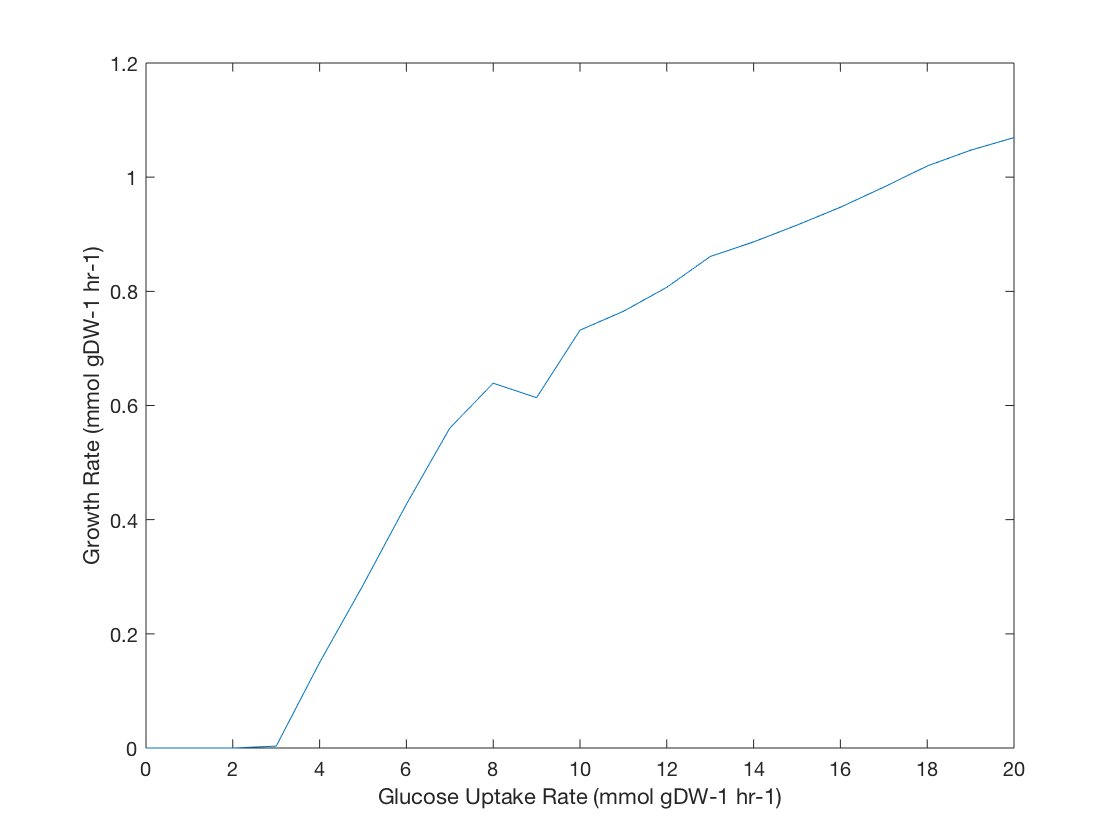

figure; 
plot(-glucoseUptakeRates,growthRates,'-')
xlabel('Glucose Uptake Rate (mmol gDW-1 hr-1)')
ylabel('Growth Rate (mmol gDW-1 hr-1)')

**Figure 5  **Robustness analysis for maximum growth rate while varying glucose uptake rate with oxygen uptake fixed at 17 mmol gDW-1 hr-1.

As expected, with a glucose uptake of 0 mmol gDW-1 hr-1, the maximum possible growth rate is 0 hr-1.  Growth remains at 0 hr-1 until a glucose uptake rate of about 2.83 mmol gDW-1 hr-1, because with such a small amount of glucose, the system cannot make 8.39 mmol gDW-1 hr-1 ATP to meet the default lower bound of the ATP maintenance reaction (ATPM).  This reaction simulates the consumption of ATP by non-growth associated processes such as maintenance of electrochemical gradients across the cell membrane.  Once enough glucose is available to meet this ATP requirement, growth increases rapidly as glucose uptake increases.  At an uptake rate of about 7.59 mmol gDW-1 hr-1, growth does not increase as rapidly.  It is at this point that oxygen and not glucose limits growth.  Excess glucose cannot be fully oxidized, so the fermentation pathways are used.

#### What is the growth rate as a function of oxygen uptake rate with glucose uptake held constant?

#### Hint: fix glucose uptake at 10 mmol gDW-1 hr-1

The oxygen uptake rate can also be varied with the glucose uptake rate held constant.  With glucose uptake fixed at 10 mmol gDW-1 hr-1, growth rate increases steadily as oxygen uptake increases (Figure 6).  At an oxygen uptake of about 21.80 mmol gDW-1 hr-1, growth actually begins to decrease as oxygen uptake increases.  This is because glucose becomes limiting at this point, and glucose that would have been used to produce biomass must instead be used to reduce excess oxygen.  In the previous example, growth rate continues to increase once oxygen become limiting because E. coli can grow on glucose without oxygen.  In this example, E. coli cannot grow with oxygen but not glucose (or another carbon source), so growth decreases when excess oxygen is added. 

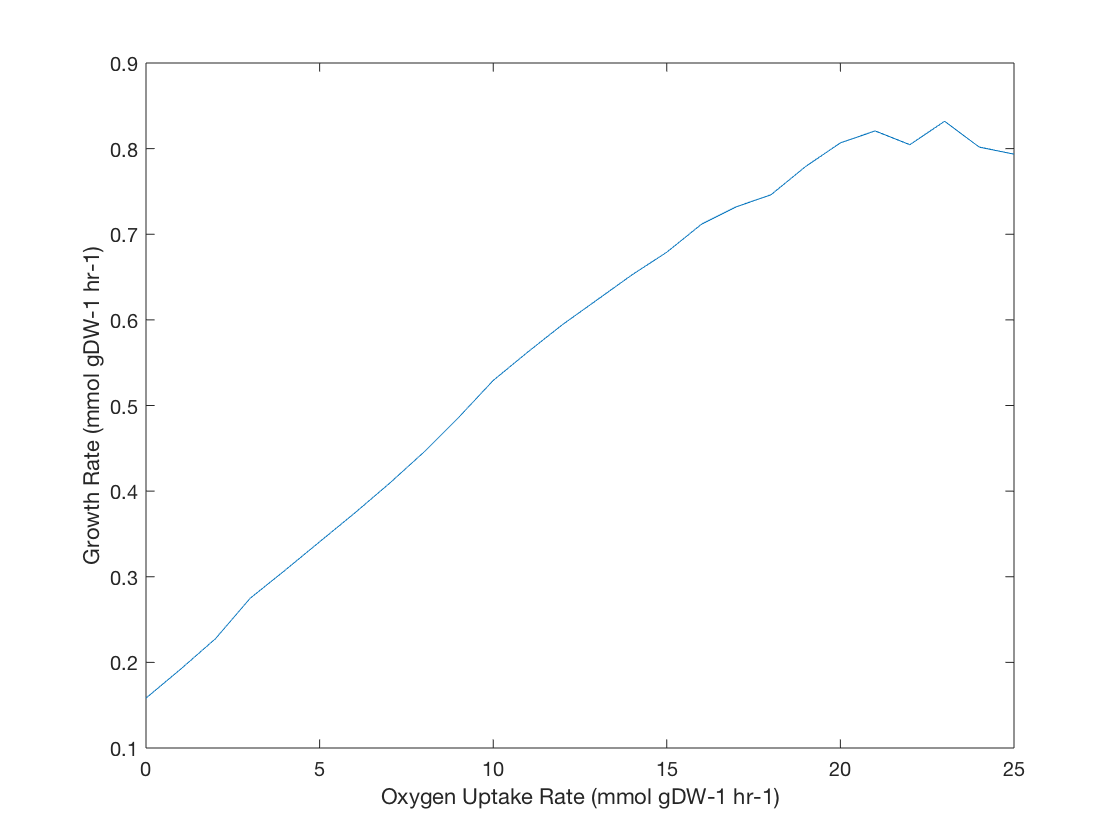

model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-10,'b');
oxygenUptakeRates = zeros(25,1);
growthRates = zeros(25,1);
for i = 0:25
	model = changeRxnBounds(model,'EX_o2(e)',-i,'b');
        oxygenUptakeRates(i+1)=-i;
	FBAsolution = optimizeCbModel(model,'max');
	growthRates(i+1) = FBAsolution.f;
end
figure; 
plot(-oxygenUptakeRates,growthRates,'-')
xlabel('Oxygen Uptake Rate (mmol gDW-1 hr-1)')
ylabel('Growth Rate (mmol gDW-1 hr-1)')

Figure 6  Robustness analysis for maximum growth rate while varying oxygen uptake rate with glucose uptake fixed at 10 mmol gDW-1 hr-1.

## Example 6.  Simulating gene knockouts

Just as growth in different environments can be simulated with FBA, gene knockouts can also be simulated by changing reaction bounds. To simulate the knockout of any gene, its associated reaction or reactions can simply be constrained to not carry flux.  By setting both the upper and lower bounds of a reaction to 0 mmol gDW-1 hr-1, a reaction is essentially knocked out, and is restricted from carrying flux.  The E. coli core model, like many other constraint-based models, contains a list of gene-protein-reaction interactions (GPRs), a list of Boolean rules that dictate which genes are connected with each reaction in the model.  When a reaction is catalyzed by isozymes (two different enzymes that catalyze the same reaction), the associated GPR contains an “or” rule, where either of two or more genes may be knocked out but the reaction will not be constrained. 

#### Which genes are required to be knocked out to eliminate flux through the phosphofructokinase (PFK) reaction?

#### Hint: study the model

The GPR for phosphofructokinase (PFK) is “b1723 (pfkB) or b3916 (pfkA),” so according to this Boolean rule, both pfkB and pfkA must be knocked out to restrict this reaction.  When a reaction is catalyzed by a protein with multiple essential subunits, the GPR contains an “and” rule, and if any of the genes are knocked out the reaction will be constrained to 0 flux.  Succinyl-CoA synthetase (SUCOAS), for example, has the GPR “b0728 (sucC) and b0729 (sucD),” so knocking out either of these genes will restrict this reaction.  Some reactions are catalyzed by a single gene product, while others may be associated with ten or more genes in complex associations.

#### What is the growth rate of E. coli when the gene b1852 (zwf) is knocked out?

#### Hint: `deleteModelGenes`

The COBRA Toolbox contains a function called `deleteModelGenes` that uses the GPRs to constrain the correct reactions.  Then FBA may be used to predict the model phenotype with gene knockouts.  For example, growth can be predicted for E. coli growing aerobically on glucose with the gene b1852 (zwf), corresponding to the reaction glucose-6-phospahte dehydrogenase (G6PDH2r), knocked out.  The FBA predicted growth rate of this strain is 1.6329 hr-1, which is slightly lower than the growth rate of 1.6531 hr-1 for wild-type E. coli because the cell can no longer use the oxidative branch of the pentose phosphate pathway to generate NADPH.  Using FBA to predict the phenotypes of gene knockouts is especially useful in predicting essential genes.  When the gene b2779 (eno), corresponding to the enolase reaction (ENO), is knocked out, the resulting growth rate on glucose is 0 hr-1.  Growth is no longer possible because there is no way to convert glucose into TCA cycle intermediates without this glycolysis reaction, so this gene is predicted to be essential.  Because FBA can compute phenotypes very quickly, it is feasible to use it for large scale computational screens for gene essentiality, including screens for two or more simultaneous knockouts.  

#### Knockout every pairwise combination of the 136 genes in the E. coli core model and display the results.

#### Hint: `doubleGeneDeletion`

Figure 8 shows the results of a double knockout screen, in which every pairwise combination of the 136 genes in the E. coli core model were knocked out.  The code to produce this figure is:

model = modelOri;
[grRatio,grRateKO,grRateWT] = doubleGeneDeletion(model);
figure;
imagesc(grRatio);
colormap('hsv')
xlabel('gene knockout 1')
ylabel('gene knockout 2')

**Figure 8  **Gene knockout screen on glucose under aerobic conditions.  Each of the 136 genes in the core E. coli model were knocked out in pairs, and the resulting relative growth rates were plotted.  In this figure, genes are ordered by their b number.  Some genes are always essential, and result in a growth rate of 0 when knocked out no matter which other gene is also knocked out.  Other genes form synthetic lethal pairs, where knocking out only one of the genes has no effect on growth rate, but knocking both out is lethal.  Growth rates in this figure are relative to wild-type.

## Example 7.  Which genes are essential for which biomass precursor? 

Earlier, we saw how to determine essential genes for growth. Here we will repeat the same analysis but instead of optimizing for the biomass production, we will optimize for the synthesis of all biomass precursors individually. 

#### Which genes are essential for synthesis of each biomass precursor?

#### Hint: `addDemandReaction`

Therefore, we have to add a demand reaction for each biomass precursor to the model and perform a gene deletion study for each demand reaction.  First, the components of the biomass reaction can be identified and demand reactions can be added by using the addDemandReaction function:

model = modelOri;
bool=model.S(:,strcmp(model.rxns,'Biomass_Ecoli_core_N(w/GAM)-Nmet2'))~=0;

Single deletion analysis to remove lethal genes
100%    [........................................]
131 non-lethal genes
Double gene deletion analysis
Total of 8515 pairs to analyze
Double gene deletion analysis in progress ...
Perc complete	CPU time


biomassComponents=model.mets(bool);
[modelBiomass,rxnNames] = addDemandReaction(model,biomassComponents);

Next, gene knockout screens can be performed with each of these demand reactions set as the objective, one at a time:

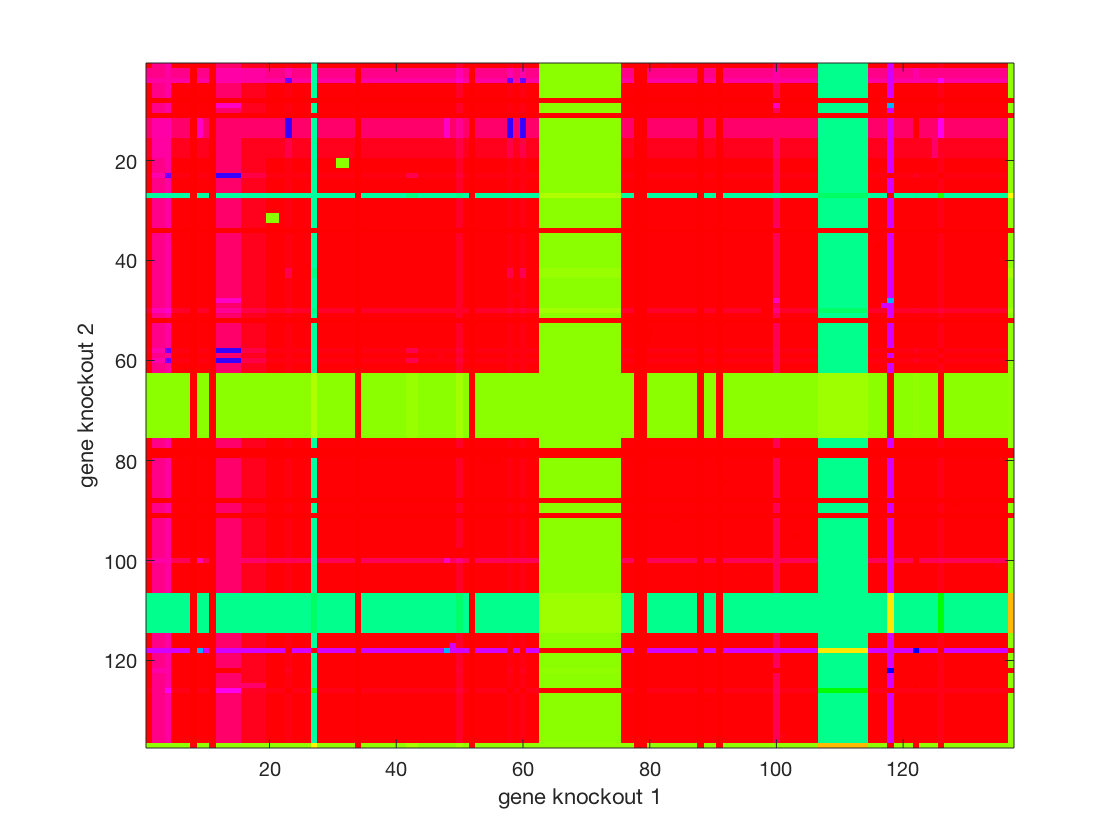


for i = 1:length(rxnNames)
    modelBiomass = changeObjective(modelBiomass,rxnNames{i});

    [grRatio,grRateKO,grRateWT,hasEffect,delRxns,fluxSolution] = singleGeneDeletion(modelBiomass,'FBA',model.genes,0);
    biomassPrecursorGeneEss(:,i) = grRateKO;
    biomassPrecursorGeneEssRatio(:,i) = grRatio;
end
%biomassPrecursorGeneEssRatio(~isfinite(biomassPrecursorGeneEssRatio))=0;

The resulting matrix biomassPrecursorGeneEssRatio is plotted with the imagesc function in Figure 9, and indicate which biomass precursors become blocked by certain gene knockouts.  

figure;
imagesc(biomassPrecursorGeneEssRatio);
colormap('hsv')
yticks(1:length(model.genes));

Adding the following reactions to the model:
DM_3pg[c]	3pg[c] 	->	
DM_accoa[c]	accoa[c] 	->	
DM_adp[c]	adp[c] 	->	
DM_akg[c]	akg[c] 	->	
DM_atp[c]	atp[c] 	->	
DM_coa[c]	coa[c] 	->	
DM_e4p[c]	e4p[c] 	->	
DM_f6p[c]	f6p[c] 	->	
DM_g3p[c]	g3p[c] 	->	
DM_g6p[c]	g6p[c] 	->	
DM_gln-L[c]	gln-L[c] 	->	
DM_glu-L[c]	glu-L[c] 	->	
DM_h2o[c]	h2o[c] 	->	
DM_h[c]	h[c] 	->	
DM_nad[c]	nad[c] 	->	
DM_nadh[c]	nadh[c] 	->	
DM_nadp[c]	nadp[c] 	->	
DM_nadph[c]	nadph[c] 	->	
DM_oaa[c]	oaa[c] 	->	
DM_pep[c]	pep[c] 	->	
DM_pi[c]	pi[c] 	->	
DM_pyr[c]	pyr[c] 	->	
DM_r5p[c]	r5p[c] 	->	


yticklabels(model.genes)

Figure 9  Gene essentiality for biomass precursor synthesis. Heat map shows the relative biomass precursor synthesis rate of mutant compared to wild-type.   The 23 biomass precursors are 3pg, accoa, adp, akg, atp, coa, e4p, f6p, g3p, g6p, gln-L, glu-L, h2o, h, nad, nadh, nadp, nadph, oaa, pep, pi, pyr, r5p.

#### Which biomass precursors cannot be net synthesised by the E. coli core model? What does this say about the E. coli core model itself?

#### Hint: think about steady state versus mass balance

Some precursors (like atp[c]) cannot be net produced by any of the gene knockout strains because of the demand reactions that consume them and there are no set of reactions that de novo synthesise that precursor.  The addDemandReacton function produces a demand reaction that does not regenerate ADP when ATP is consumed or NAD+ when NADH is consumed, so these reactions cannot carry flux at steady-state. The genome-scale E. coli model contains all the reactions for de novo synthesis of ATP.

## Example 8.  Which non-essential gene knockouts have the greatest effect on the network flexibility?

Another question one might be interested in asking is what are the consequences for the network of deleting a non-essential gene? Given an objective, the flux span is the difference between the maximium and minimum alternate optimal flux values for a reaction. A reaction is said to become more flexible if its flux span increases and less flexible if its flux span decreases.

#### What reactions are increased and decreased in flux span in response to deletion of these 6 genes?  `{'b0114', 'b0723', 'b0726', 'b0767', 'b1602', 'b1702'} With reference to a particular example, w`hat is the biochemical interpretation of an increased flux span in response to a gene deletion? 

#### Hint: `fluxVariability`, `hist`

To address this question, first delete the network genes individually (a single gene deletion study) and then perform FVA (Example 3) on non-essential gene deletion strains. In many cases one would expect that the deletion of a gene has only minor consequences to the network, especially if the deletion does not alter the maximal growth rate. In some cases however, the deletion may reduce the overall network flexibility or maybe even increase the flux range through specific reactions. In fact, this latter property is used to design optimal production strains (e.g., using OptKnock [9]), by redirecting fluxes through the network. 

The absolute flux span is a measure of flux range for each reaction. It is calculated as fi = abs(vmax,i – vmin,i), where vmin,i and vmax,i are the minimal and maximal flux rate as determined using FVA.  First, calculate wild-type flux variability:

[minFluxAll(:,1),maxFluxAll(:,1)] = fluxVariability(model);

1111111111111111111111100%    [........................................]


Next, calculate the knockout strain flux variablities and flux spans:

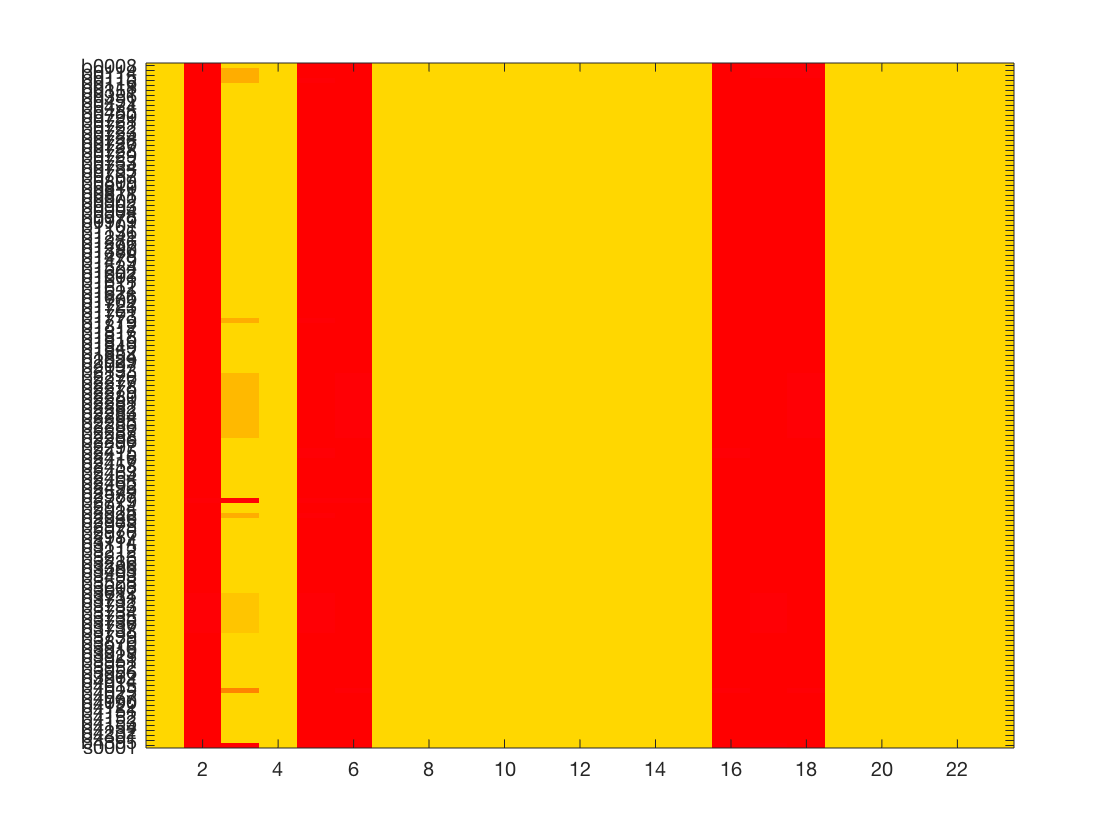

genes=model.genes([2,14,16,23,42,48]);
for i = 1 : length(genes)
    [modelDel] = deleteModelGenes(model,genes{i});
    [minFluxAll(:,i+1),maxFluxAll(:,i+1)] = fluxVariability(modelDel);
end


fluxSpan = abs(maxFluxAll - minFluxAll);
for i = 1 : size(fluxSpan,2)
    fluxSpanRelative(:,i) = fluxSpan(:,i)./fluxSpan(:,1);
end

This example with six mutant strains shows that the majority of the network reactions have reduced flux span compared to wild-type (Figure 10). However, some of these knockout strains have a few reactions which have much higher flux span than wildtype. For example, in one of the knockout strains (ΔsucA), the flux span is increased 14 times through the phosphoenolpyruvate carboxykinase reaction (PPCK).

Finally, histograms can be plotted to show how many reactions have increased or decreased flux spans for each knockout:

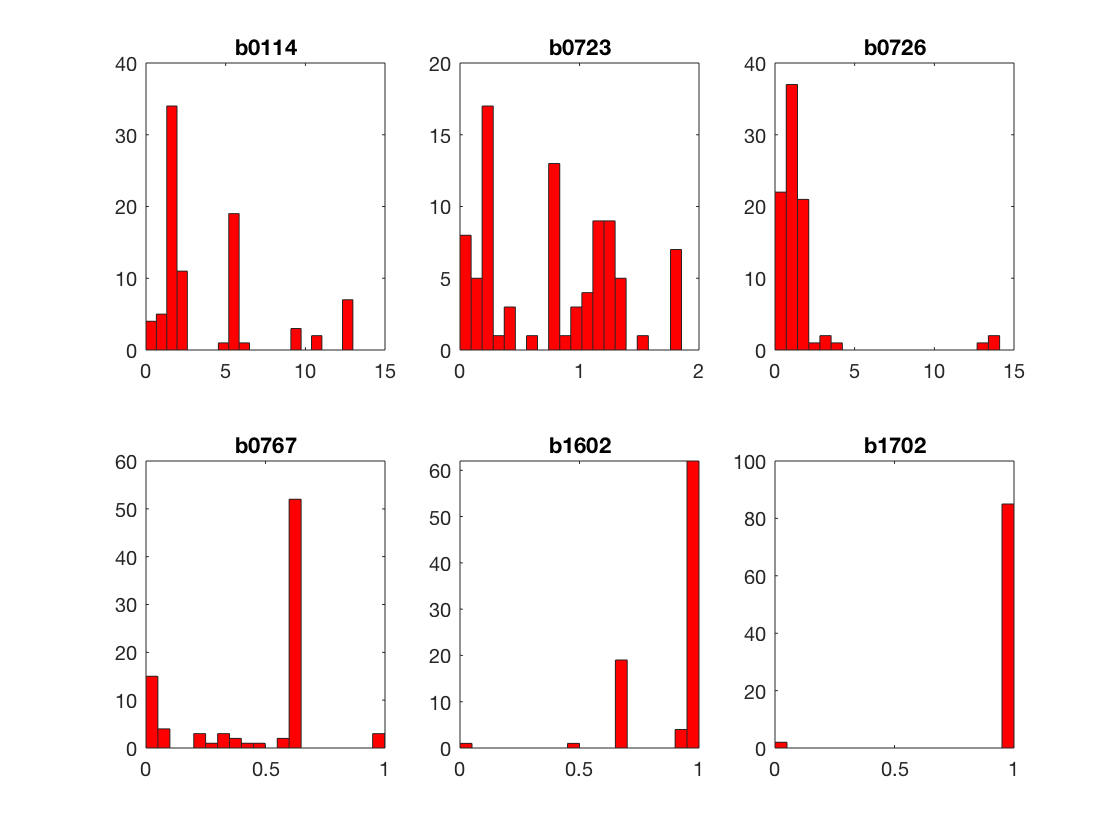

for i =2:7
    subplot(2,3,i-1)
    hist(fluxSpanRelative(:,i),20);
    title(genes{i-1});
end

Figure 10  Histograms of relative flux spans for 6 gene knockout mutants.

## TIMING

*2 hrs*

## *Acknowledgments*

This tutorial was originally written by Jeff Orth and Ines Thiele for the publication "What is flux balance analysis?"

## REFERENCES

1.	Becker, S.A. et al. Quantitative prediction of cellular metabolism with constraint-based models: The COBRA Toolbox. Nat. Protocols 2, 727-738 (2007).

2.	Orth, J.D., Fleming, R.M. & Palsson, B.O. in EcoSal - Escherichia coli and Salmonella Cellular and Molecular Biology. (ed. P.D. Karp) (ASM Press, Washington D.C.; 2009).

3.	Covert, M.W., Knight, E.M., Reed, J.L., Herrgard, M.J. & Palsson, B.O. Integrating high-throughput and computational data elucidates bacterial networks. Nature 429, 92-96 (2004).

4.	Segre, D., Vitkup, D. & Church, G.M. Analysis of optimality in natural and perturbed metabolic networks. Proceedings of the National Academy of Sciences of the United States of America 99, 15112-15117 (2002).

5.	Shlomi, T., Berkman, O. & Ruppin, E. Regulatory on/off minimization of metabolic flux changes after genetic perturbations. Proceedings of the National Academy of Sciences of the United States of America 102, 7695-7700 (2005).

6.	Reed, J.L., Famili, I., Thiele, I. & Palsson, B.O. Towards multidimensional genome annotation. Nat Rev Genet 7, 130-141 (2006).

7.	Satish Kumar, V., Dasika, M.S. & Maranas, C.D. Optimization based automated curation of metabolic reconstructions. BMC bioinformatics 8, 212 (2007).

8.	Kumar, V.S. & Maranas, C.D. GrowMatch: an automated method for reconciling in silico/in vivo growth predictions. PLoS Comput Biol 5, e1000308 (2009).

9.	Burgard, A.P., Pharkya, P. & Maranas, C.D. Optknock: a bilevel programming framework for identifying gene knockout strategies for microbial strain optimization. Biotechnology and bioengineering 84, 647-657 (2003).

10.	Patil, K.R., Rocha, I., Forster, J. & Nielsen, J. Evolutionary programming as a platform for in silico metabolic engineering. BMC bioinformatics 6, 308 (2005).

11.	Pharkya, P., Burgard, A.P. & Maranas, C.D. OptStrain: a computational framework for redesign of microbial production systems. Genome research 14, 2367-2376 (2004).

12.	Varma, A. & Palsson, B.O. Metabolic capabilities of Escherichia coli: I. Synthesis of biosynthetic precursors and cofactors. Journal of Theoretical Biology 165, 477-502 (1993).

13.	Mahadevan, R. & Schilling, C.H. The effects of alternate optimal solutions in constraint-based genome-scale metabolic models. Metabolic engineering 5, 264-276 (2003).

14.	Edwards, J.S. & Palsson, B.O. Robustness analysis of the Escherichia coli metabolic network. Biotechnology Progress 16, 927-939 (2000).

15.	Edwards, J.S., Ramakrishna, R. & Palsson, B.O. Characterizing the metabolic phenotype: a phenotype phase plane analysis. Biotechnology and bioengineering 77, 27-36. (2002).

16.	Bell, S.L. & Palsson, B.O. Phenotype phase plane analysis using interior point methods. Computers & Chemical Engineering 29, 481-486 (2005).

17.	Palsson, B.O. Systems biology: properties of reconstructed networks. (Cambridge University Press, New York; 2006).

18.	Barabasi, A.L. & Oltvai, Z.N. Network biology: understanding the cell's functional organization. Nat Rev Genet 5, 101-113 (2004).

19.	Mahadevan, R. & Palsson, B.O. Properties of metabolic networks: structure versus function. Biophysical journal 88, L07-09 (2005).

20.	Price, N.D., Schellenberger, J. & Palsson, B.O. Uniform Sampling of Steady State Flux Spaces: Means to Design Experiments and to Interpret Enzymopathies. Biophysical journal 87, 2172-2186 (2004).

21.	Thiele, I., Price, N.D., Vo, T.D. & Palsson, B.O. Candidate metabolic network states in human mitochondria: Impact of diabetes, ischemia, and diet. The Journal of biological chemistry 280, 11683-11695 (2005).

22. Laurent Heirendt & Sylvain Arreckx, Thomas Pfau, Sebastian N. Mendoza, Anne Richelle, Almut Heinken, Hulda S. Haraldsdottir, Jacek Wachowiak, Sarah M. Keating, Vanja Vlasov, Stefania Magnusdottir, Chiam Yu Ng, German Preciat, Alise Zagare, Siu H.J. Chan, Maike K. Aurich, Catherine M. Clancy, Jennifer Modamio, John T. Sauls, Alberto Noronha, Aarash Bordbar, Benjamin Cousins, Diana C. El Assal, Luis V. Valcarcel, Inigo Apaolaza, Susan Ghaderi, Masoud Ahookhosh, Marouen Ben Guebila, Andrejs Kostromins, Nicolas Sompairac, Hoai M. Le, Ding Ma, Yuekai Sun, Lin Wang, James T. Yurkovich, Miguel A.P. Oliveira, Phan T. Vuong, Lemmer P. El Assal, Inna Kuperstein, Andrei Zinovyev, H. Scott Hinton, William A. Bryant, Francisco J. Aragon Artacho, Francisco J. Planes, Egils Stalidzans, Alejandro Maass, Santosh Vempala, Michael Hucka, Michael A. Saunders, Costas D. Maranas, Nathan E. Lewis, Thomas Sauter, Bernhard Ø. Palsson, Ines Thiele, Ronan M.T. Fleming, **Creation and analysis of biochemical constraint-based models: the COBRA Toolbox v3.0**, Nature Protocols, volume 14, pages 639–702, 2019 [doi.org/10.1038/s41596-018-0098-2](https://doi.org/10.1038/s41596-018-0098-2).